# [Image Classification: Bits and Cracks](https://apmonitor.com/pds/index.php/Main/BitClassification)

## Bit Classification

**Objective**: Train and test a Convolutional Neural Network to detect [drilling bit types](https://en.wikipedia.org/wiki/Drill_bit_well): [roller cone](https://petrowiki.spe.org/Roller_cone_bit_design), [Polycrystalline Diamond Compact (PDC)](https://petrowiki.spe.org/PDC_drill_bits), and spoon types.

Deep Learning (DL) is a subset of Machine Learning that uses Neural Network inspired architecture to make predictions. Convolutional Neural Networks (CNN) are a type of DL model that is effective in learning patterns in 2-dimensional data such as images. Images of drill bit types are used to train a classifier to identify common drill bit types for Oil & Gas Exploration and Horizontal Directional Drilling (HDD).

This exercise demonstrates the use of image classification to distinguish between objects in photos. Although applied to bit types, the same methods and code can be used for any type or number of objects. This example can be modified by including train and test photos in folders that are named with the object type. The code automatically takes the name of the folder as the photo label for training the classifier. An additional example of an image-based CNN is found in the [Soil Classification Case Study](https://apmonitor.com/pds/index.php/Main/SoilClassification).

For a time comparision, this Live Script was clocked on a computer with the following specs:

Processor	11th Gen Intel(R) Core(TM) i7-1195G7 @ 2.90GHz   2.92 GHz

Installed RAM	16.0 GB (15.8 GB usable)

System type	64-bit operating system, x64-based processor

This exercise uses photos of drill bit types in a compressed archive.

 [**Download: bit_photos.zip**](https://apmonitor.com/pds/uploads/Main/bit_photos.zip)

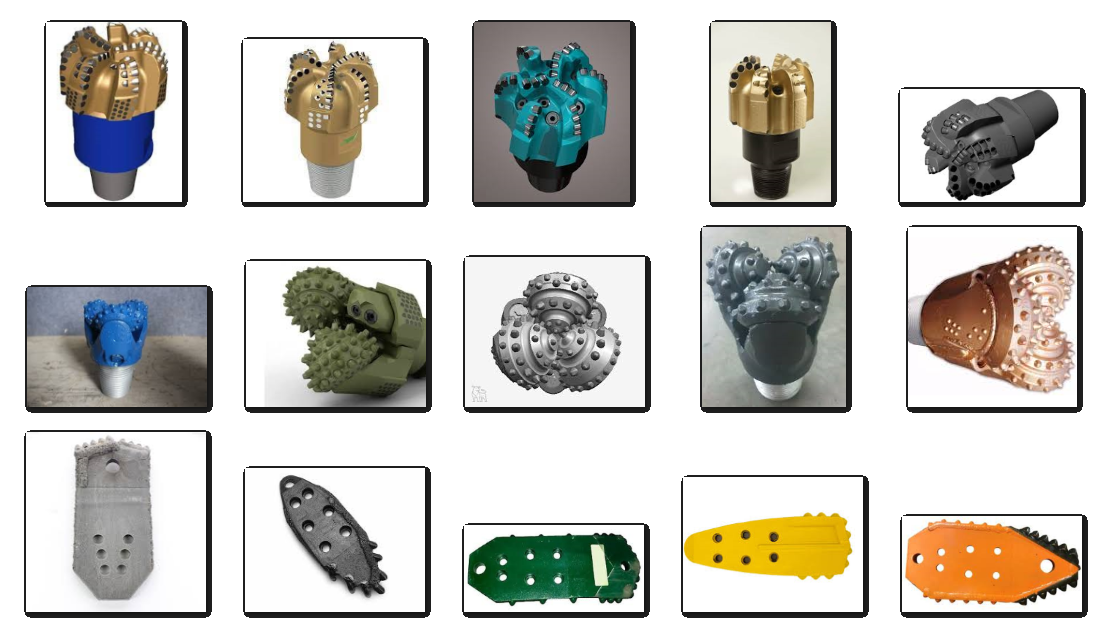

The archive contains two folders, a test folder and train folder with subdirectories corresponding to the possible drill bit types (PDC, Roller Cone, and Spoon). The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───PDC`

`  │   ├───Roller Cone`

`  │   └───Spoon`

`  └───train`

`  |   ├───PDC`

`  |   ├───Roller Cone`

`  |   └───Spoon`

The photos are imported into the MATLAB session. The first step is to process the images into a format that 1) makes the data readable to the model, and 2) provides more training material for the model to learn. For example, the *train_processor* variable scales the data so that it can be a feature (input) for the model, but also takes each images and augments it so that the model can learn from multiple variations of the same picture. It flips it horizontally, rotates it, and shifts it, and more to make sure the model learns from the shape of the bit rather than the orientation or size.

Below is the code for bit classification

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/bit_photos.zip';
filename = 'bit_photos.zip';
websave(filename,url);

% Unzip then deleate zip folder
unzip(filename);
delete(filename);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [.8 1.2]);

% Load data
train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train, 'DataAugmentation', train_processor);

### **Build Neural Network**

Change these values to modify the training neural network. Beware, the larger the values, the longer and more computer memory demand will be required. This is a starting point and should take roughly 10 minutes.

num_training_epochs = 10;

Build the Neural Network based on the values above

layers = [imageInputLayer([255 255 3]); % Specifies the dimensions of the input data
            convolution2dLayer([3 3],20); % Applies 20 filters of size 3x3 to the input data
            reluLayer(); % ReLU sets negative values to zero and keeps positive values unchanged
            maxPooling2dLayer([2 2]); % Max pooling reduces the spatial dimensions by selecting the maximum value within each 2x2 region
            fullyConnectedLayer(3); % Creates a fully connected layer with 3 neurons
            softmaxLayer(); % Converts output values to a probability distribution
            classificationLayer(); % Assigns the classification based upon the probabilities
            ];

options = trainingOptions("adam", ... % Use the Adam optimizer as the optimization algorithm
    InitialLearnRate=0.01, ... % Set the initial learn rate
    SquaredGradientDecayFactor=0.99, ... % Sets the squared gradient term to decay by 1% at each time step (prevents over fluctuation)
    MaxEpochs=num_training_epochs, ... % Sets the maximum number of times the classifier will go through the entire dataset 
    MiniBatchSize=32, ... % Sets the data to be split into smaller batch sizes of 32
    Verbose=true,... % Displays training progress during training
    Plots="training-progress");

**Build the CNN model with the Deep Network Designer**

Click on Apps in the Ribbon. Click on the Neural Network Designer under the Machine Learning and Deep Learning section. When the pop-up comes up, click New on the Blank Network. Next, you can drag and drop the layers from the left hand side to the Designer tab. Once all layers on set in the Designer tab, link the layers in order with the arrows. You can change the number of layers to your desire (remember the more layers in your neural network, the more computing power required).

For more details on how to design the neural network, refer to the Soil Classification case study.

### Train Neural Network 

(estimated time: 5 minutes)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       25.00% |      60.5201 |          0.0100 |
|      10 |          10 |       00:00:21 |       34.38% |   49543.0664 |          0.0100 |
|========================================================================================|
Training finished: Max epochs completed.


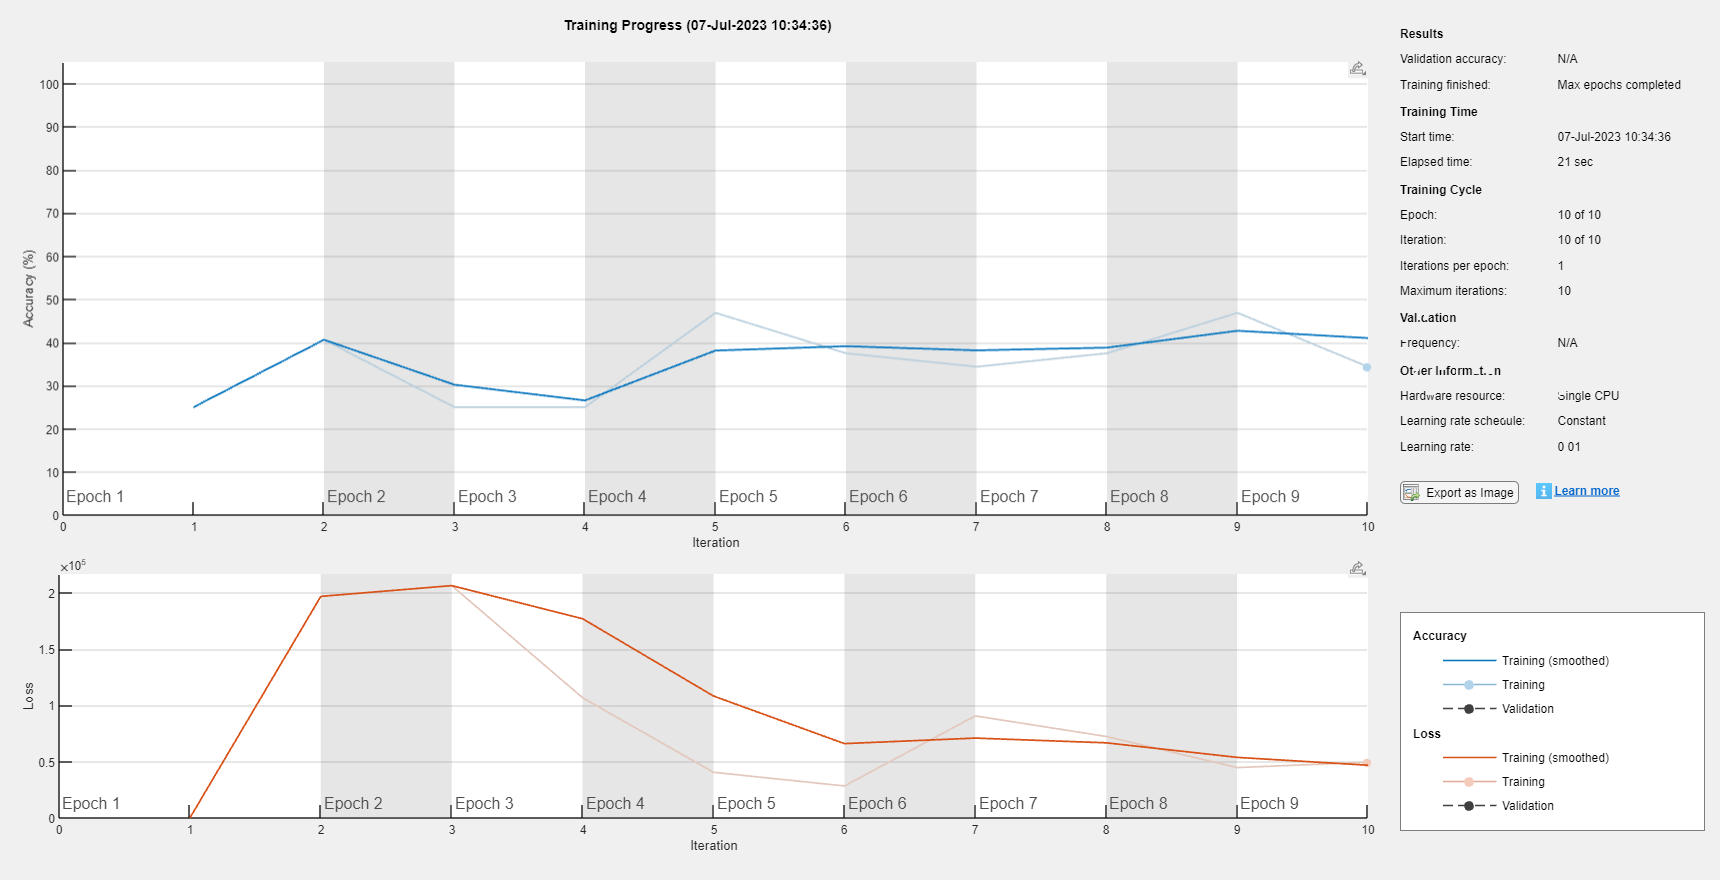

[net,~] = trainNetwork(train_preprocess, layers, options);

**Train Neural Network with the Deep Network Designer**

Click on the Data tab and click Import Data in the top left. Click Import Custom Data. On the pop-up, select train_preprocess for the training data and click None for the Validation data. Ignore the warning. Import. Now click on the training tab and click Training Options in the top left. Change the Number of Epochs to 10 and exit out of the pop-up. Now click Train.

### Test Neural Network

Grab random test drill bit and predict the type.

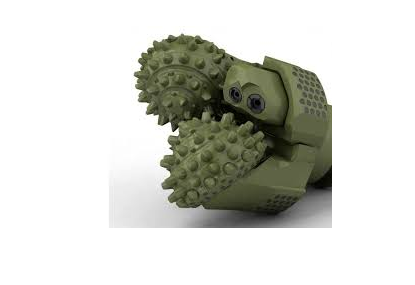

% Grab random picutre
btype = ["PDC", "Roller Cone", "Spoon"]; % possible output values
bbtype = ["PDC", "Roller_Cone", "Spoon"]; % possible output values
rng('shuffle');
i=randi(3);
j=randi(5);
b = btype(i);
bb = bbtype(i);
im = strcat(lower(strrep(strcat(bb,'_',num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Show image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image
imshow(ime);


% Modify image to fit Neural Network
im = double(imresize(ime,[255 255]));

% Prediction
disp(['Predicted: ', net.classify(im)])

     Predicted:      Spoon 



true_value = regexp(image_fp, "(PDC)|(Roller Cone)|(Spoon)", 'match');
disp(['True value: ', true_value{1}])

True value: Roller Cone


The validation accuracy as well as individual testing shows that there are misclassifications.

Here are a few things that can improve the accuracy for this application:

- **More photos!** This is the most important thing, Machine Learning typically requires many photos that are representative of what the classifiers see. At this point, there are not nearly enough photos for the model to learn each bit type.

- **Background Clutter.** Most of the images in this set have the background removed. To train a classifier to identify bit types in the field, more photos with realistic backgrounds are needed. Synthetic backgrounds can also be added.

- **Hyperparameter Optimization.** To make the best model, the best parameters must be selected to maximize the accuracy (hyperparameter optimization). Hyperparameters can be adjusted throught the Experiment Manager, further details can be found in this [link](https://www.mathworks.com/help/deeplearning/experiment-manager.html).

## Crack Classification

Replace the photos in the bit classification case study to build a classifier to distinguish photos of concrete with a crack (Positive) or no crack (Negative).

 [**Download: concrete_cracks.zip**](https://apmonitor.com/pds/uploads/Main/concrete_cracks.zip)

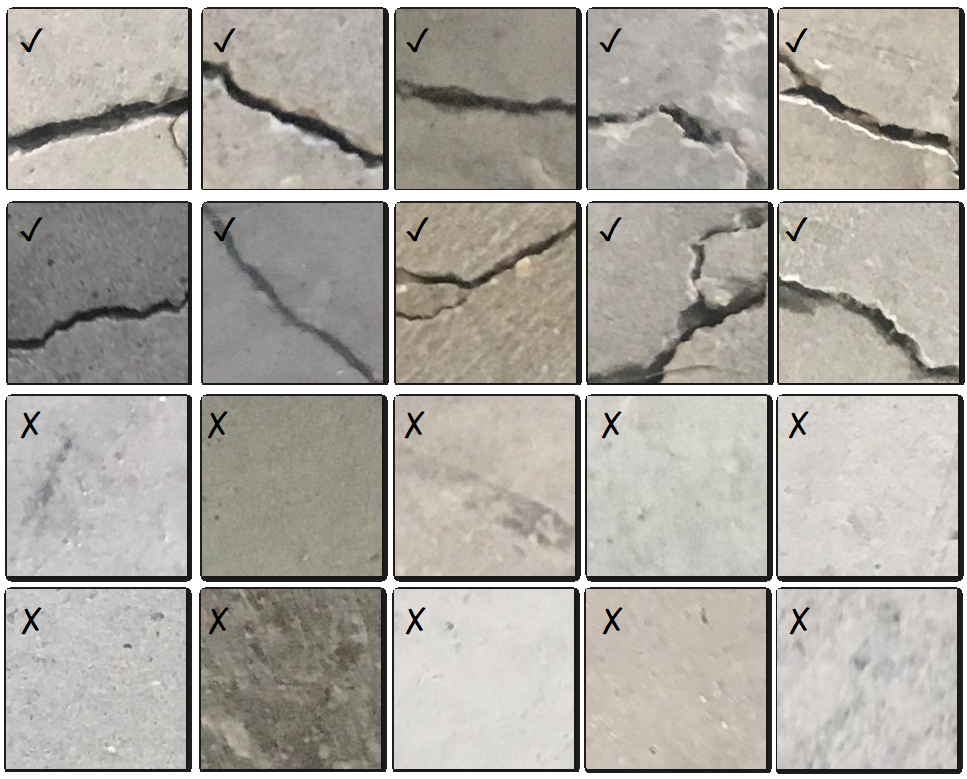

The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───Positive`

`  │   └───Negative`

`  └───train`

`      ├───Positive`

`      └───Negative`

The dataset is divided into two (negative and positive) crack image folders for image classification. Each train folder has 500 images with a total of 1000 images with 227 x 227 pixels with RGB channels. The test folders have 100 images from the full image set for a total of 200 test images. The partial dataset trains much faster and gives similar accuracy (95%) versus 97% for the full data set with 40,000 images.

% Clean the workspace and the folders from above
clear;
rmdir('train','s');
rmdir('test','s');

url = 'http://apmonitor.com/pds/uploads/Main/concrete_cracks.zip';
filename = 'concrete_cracks.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1]);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);

% Load data
train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess_con = augmentedImageDatastore([128,128],train, 'DataAugmentation', train_processor);

### **Build Neural Network**

Change these values to modify the training neural network. Beware, the larger the values, the longer and more computer memory demand will be required. This is a starting point and should take roughly 10 minutes.

num_conv_layers = 2;
layer_size = 16;
num_training_epochs = 5;

Build the Neural Network based on the values above

% Create a cell for the layers
layers = cell((num_conv_layers+1)*3+1,1);
layers{1} = imageInputLayer([128 128 3]);
layers{2} = convolution2dLayer([3 3],layer_size);
layers{3} = reluLayer();
layers{4} = maxPooling2dLayer([2 2]);

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1 
    layers{i*3 + 2} = convolution2dLayer([3 3],layer_size);
    layers{i*3 + 3} = reluLayer();
    layers{i*3 + 4} = maxPooling2dLayer([2 2]);
end
layers{end - 2} = fullyConnectedLayer(2);
layers{end - 1} = softmaxLayer();
layers{end} = classificationLayer();

% Convert the cell into a regular array
layers = [layers{:}];

options = trainingOptions("adam", ...
    InitialLearnRate=0.01, ...
    SquaredGradientDecayFactor=0.99, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    Plots="training-progress");

### Train Neural Network 

(estimated time: 5 minutes)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       53.12% |       7.5777 |          0.0100 |
|       2 |          50 |       00:00:48 |       59.38% |       0.6922 |          0.0100 |
|       4 |         100 |       00:01:28 |       62.50% |       0.6926 |          0.0100 |
|       5 |         150 |       00:02:13 |       43.75% |       0.6954 |          0.0100 |
|       5 |         155 |       00:02:18 |       56.25% |       0.6916 |          0.0100 |
|========================================================================================|
Training finished: Max epoc

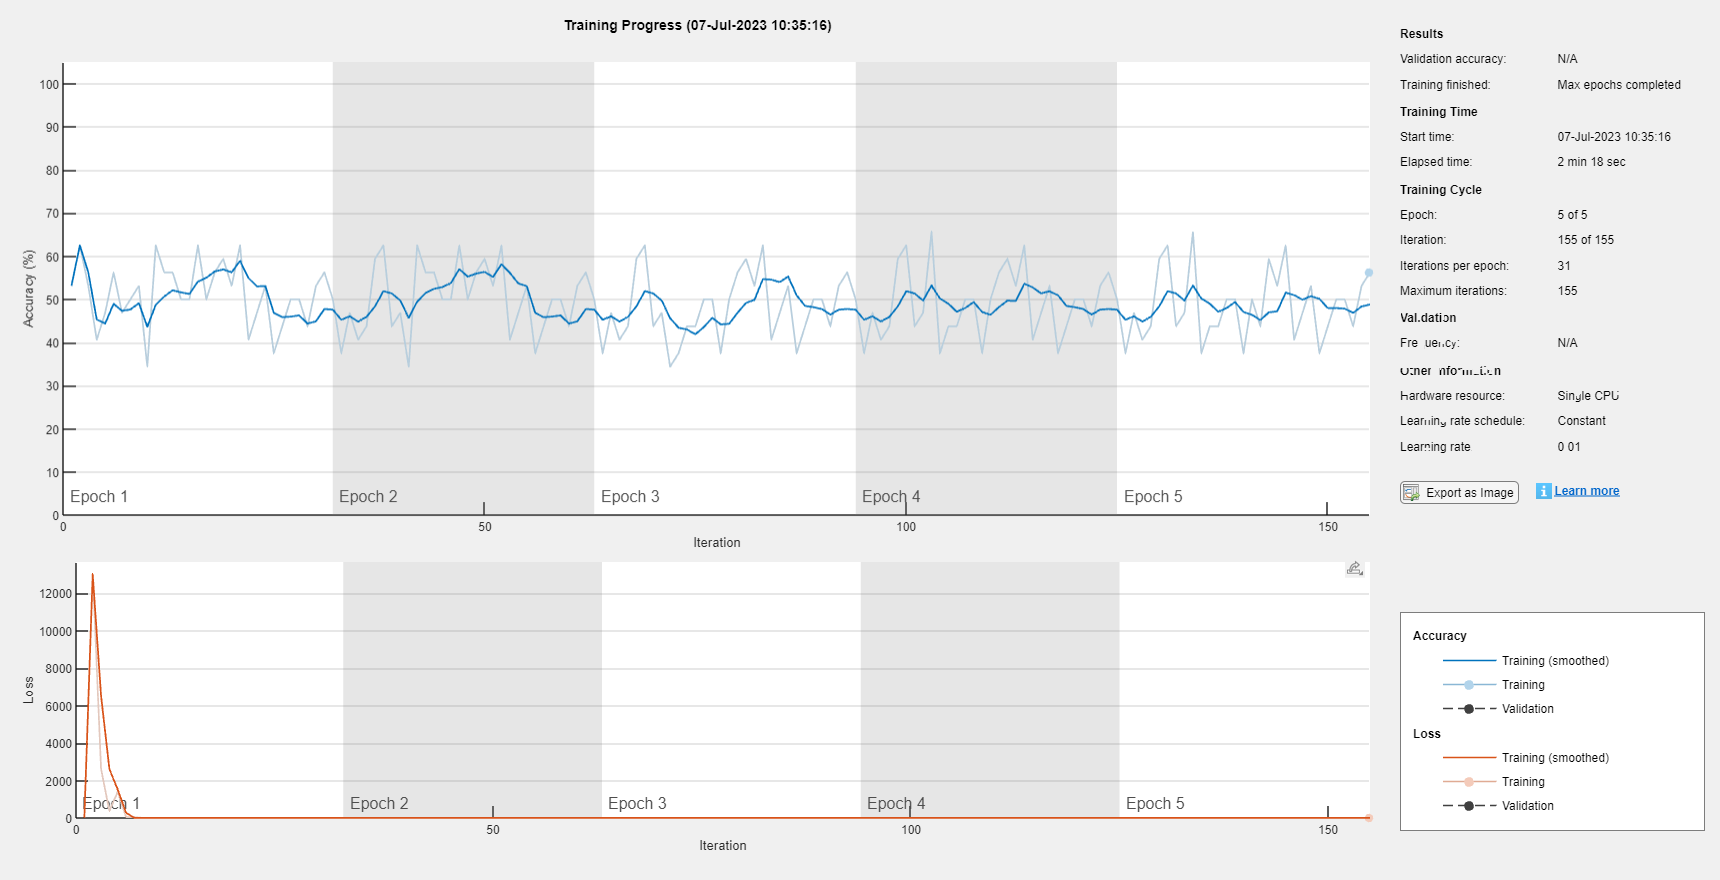

[net,info] = trainNetwork(train_preprocess_con, layers, options);

### Test Neural Network

Grab random test image and predict the type.

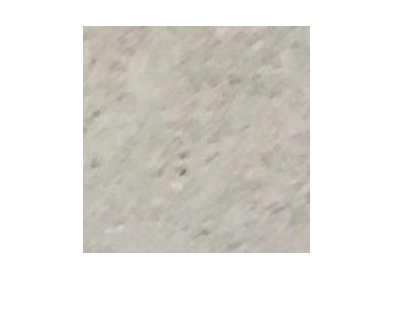

btype = ["Positive", "Negative"]; % possible output values
rng('shuffle');
i=randi(2);
j=randi([19901,20000]);
b = btype(i);
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Show image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image
imshow(ime);


% Modify image for Neural Network
im = double(imresize(ime,[128 128]));

% Prediction
disp(['Predicted',net.classify(im)])

     Predicted      Negative 



true_value = regexp(image_fp, "(Positive)|(Negative)", 'match');
disp(['True value: ', true_value{1}])

True value: Negative
